# test variance of M2 and M2c

bin_flag = (10:10:100)';
binvalue = repmat(100,[10 1]);
sample_number = 1e6;
binvalue_rep = repmat(binvalue,[1 sample_number]);
r_sample = poissrnd(binvalue_rep);

%---------calculate moments-----------
M1_samples = sum(r_sample.*bin_flag,1)./sum(r_sample,1);
M2_samples = sum(r_sample.*bin_flag.^2)./sum(r_sample,1);
M2c_samples = M2_samples-M1_samples.^2;

EM1 = sum(bin_flag.*binvalue)./sum(binvalue);
EM2 = sum(bin_flag.^2.*binvalue)./sum(binvalue);
EM2c = EM2-EM1.^2;

## display the result

mean(M1_samples)

ans = 55.0003

mean(M2_samples)

ans = 3.8500e+03

mean(M2c_samples)

ans = 824.1722


var(M1_samples)

ans = 0.8264

var(M2_samples)

ans = 1.0529e+04

var(M2c_samples)

ans = 528.1914

## calculate the derivate of each moments to the timebin

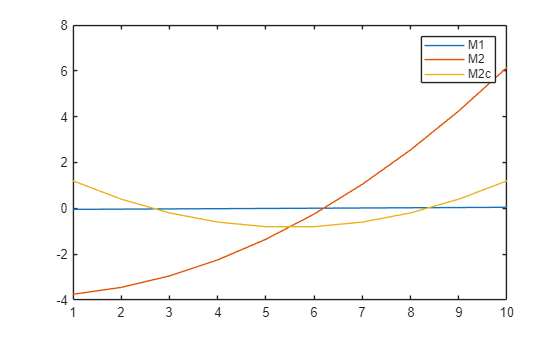

dM1_dbin = (bin_flag-EM1)./sum(binvalue);
dM2_dbin = (bin_flag.^2-EM2)./sum(binvalue);
dM2c_dbin = ((bin_flag-EM1).^2-EM2c)./sum(binvalue);

close all;
figure;
plot(dM1_dbin); hold on
plot(dM2_dbin);
plot(dM2c_dbin);
legend('M1','M2','M2c')

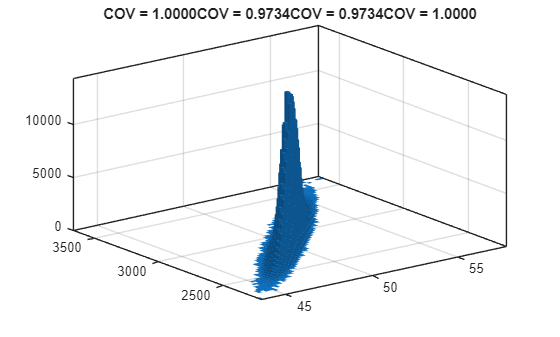

%% test the correlation of dM1 dM2
rng('default')
bin_flag = (10:10:100)';
binvalue = round(normpdf((1:10)',5,2)*200);
sample_number = 1e6;
binvalue_rep1 = repmat(binvalue,[1 sample_number]);
binvalue_rep2 = repmat(binvalue+1,[1 sample_number]);


r_sample1 = poissrnd(binvalue_rep1);
r_sample2 = poissrnd(binvalue_rep2);

Em1 = bin_flag'*binvalue./sum(binvalue);
Em2 = bin_flag'.^2*binvalue./sum(binvalue);
Ev = Em2-Em1^2;


%---------calculate moments-----------
M0_samples1 = sum(r_sample1,1);
M1_samples1 = sum(r_sample1.*bin_flag,1)./sum(r_sample1,1);
M2_samples1 = sum(r_sample1.*bin_flag.^2)./sum(r_sample1,1);
M2c_samples1 = M2_samples1-M1_samples1.^2;

J_m1 = (bin_flag-Em1)./sum(binvalue);
J_m2 = (bin_flag.^2-Em2)./sum(binvalue);
J_v = ((bin_flag-Em1).^2-Ev)./sum(binvalue);

figure; histogram2(M1_samples1,M2_samples1);
title(sprintf('COV = %.4f',corrcoef(M1_samples1,M2_samples1)));

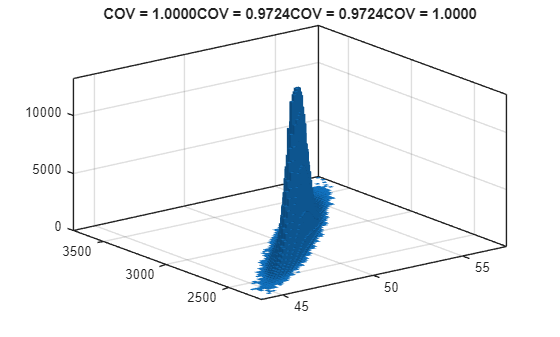


M1_samples2 = sum(r_sample2.*bin_flag,1)./sum(r_sample2,1);
M2_samples2 = sum(r_sample2.*bin_flag.^2)./sum(r_sample2,1);
M2c_samples2 = M2_samples2-M1_samples2.^2;
figure; histogram2(M1_samples2,M2_samples2);
title(sprintf('COV = %.4f',corrcoef(M1_samples2,M2_samples2)));

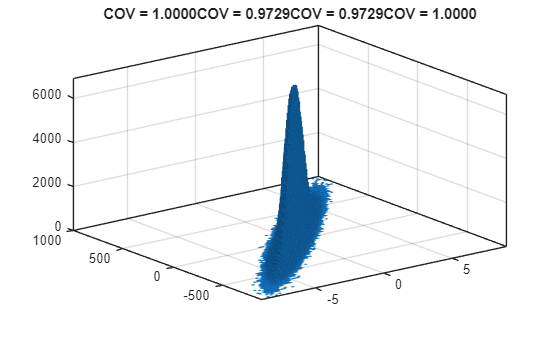



figure; histogram2(M1_samples2-M1_samples1,M2_samples2-M2_samples1);
title(sprintf('COV = %.4f',corrcoef(M1_samples2-M1_samples1,M2_samples2-M2_samples1)));


%--------------show the correlation coefficient--------
corrcoef(M1_samples1,M2_samples1)

ans =     1.0000    0.9734
    0.9734    1.0000


corrcoef(M1_samples1,M2c_samples1)

ans =     1.0000    0.0824
    0.0824    1.0000


corrcoef(M2_samples1,M2c_samples1)

ans =     1.0000    0.3077
    0.3077    1.0000


corrcoef(M0_samples1,M1_samples1)

ans =     1.0000    0.0007
    0.0007    1.0000


corrcoef(M0_samples1,M2_samples1)

ans =     1.0000    0.0007
    0.0007    1.0000


corrcoef(M0_samples1,M2c_samples1)

ans =     1.0000    0.0044
    0.0044    1.0000


var_m1 = J_m1'*diag(binvalue)*J_m1

var_m1 = 1.8364

var_m2 = J_m2'*diag(binvalue)*J_m2

var_m2 = 2.0575e+04

var_V = J_v'*diag(binvalue)*J_v

var_V = 1.0867e+03


var(M1_samples1)

ans = 1.8459

var(M2_samples1)

ans = 2.0677e+04

var(M2c_samples1)

ans = 1.0873e+03